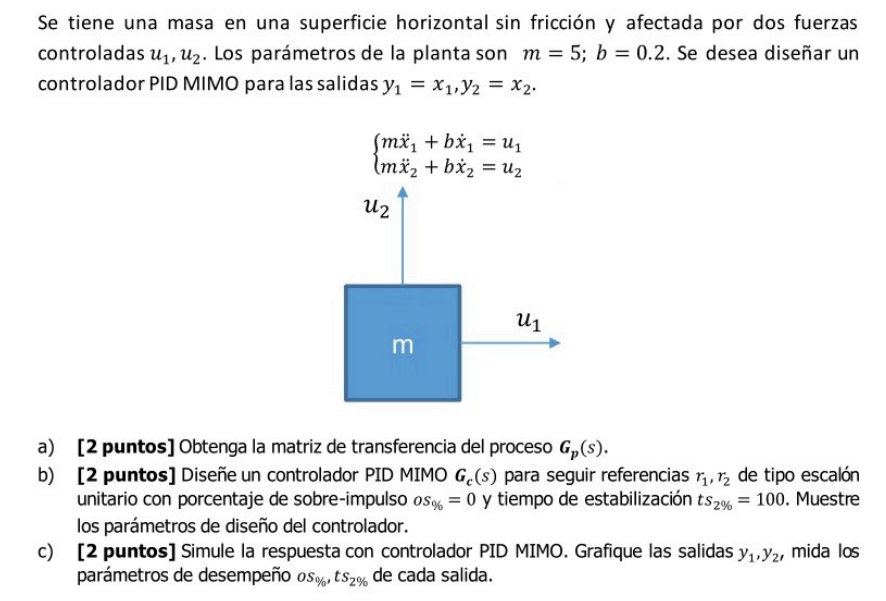

clear all
close all
clc
%Parametros
s=tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


m=5;
b=0.2;
ts2=100;
%Espacio estados
A=[-b/m 0;
    0  -b/m]

A =    -0.0400         0
         0   -0.0400


B=[1/m 0;
    0  1/m]

B =     0.2000         0
         0    0.2000


C=[1 0;
   0 1]

C =      1     0
     0     1


D=[0 0; 0 0]

D =      0     0
     0     0


Sp=ss(A,B,C,D)


Sp =
 
  A = 
          x1     x2
   x1  -0.04      0
   x2      0  -0.04
 
  B = 
        u1   u2
   x1  0.2    0
   x2    0  0.2
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


G=tf(Sp)


G =
 
  From input 1 to output...
         0.2
   1:  --------
       s + 0.04
 
   2:  0
 
  From input 2 to output...
   1:  0
 
         0.2
   2:  --------
       s + 0.04
 
Continuous-time transfer function.
Model Properties


tau=ts2/4

tau = 25

Gl=[1/(s*tau) 0;
    0     1/(s*tau)]


Gl =
 
  From input 1 to output...
        1
   1:  ----
       25 s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
        1
   2:  ----
       25 s
 
Continuous-time transfer function.
Model Properties


Gc=inv(G)*Gl


Gc =
 
  From input 1 to output...
       5 s + 0.2
   1:  ---------
         25 s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       5 s + 0.2
   2:  ---------
         25 s
 
Continuous-time transfer function.
Model Properties


Gt=feedback(G*Gc,eye(2))


Gt =
 
  From input 1 to output...
          0.04 s + 0.0016
   1:  ---------------------
       s^2 + 0.08 s + 0.0016
 
   2:  0
 
  From input 2 to output...
   1:  0
 
          0.04 s + 0.0016
   2:  ---------------------
       s^2 + 0.08 s + 0.0016
 
Continuous-time transfer function.
Model Properties


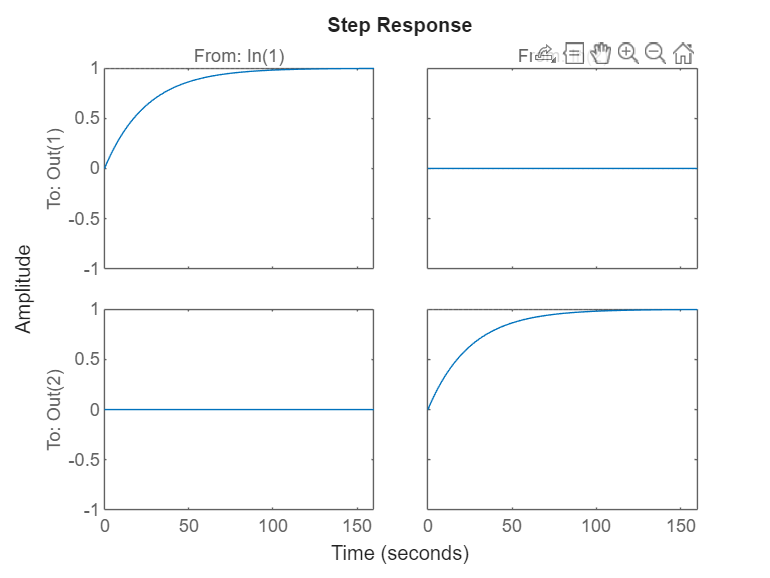

step(Gt)

stepinfo(Gt(1,1))

ans = struct with fields:
         RiseTime: 54.9252
    TransientTime: 97.8019
     SettlingTime: 97.8019
      SettlingMin: 0.9045
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 183.0555


stepinfo(Gt(2,2))

ans = struct with fields:
         RiseTime: 54.9252
    TransientTime: 97.8019
     SettlingTime: 97.8019
      SettlingMin: 0.9045
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 183.0555
